clc;
clear;
close all;

% --- PARAMETRELER --- DOWNLINK
M_verici_vektoru = [4, 8, 16]; % Verici (AP) anten sayısını artırıyoruz
M_alici = 4;                    % Alıcı (Kullanıcı) anten sayısı sabit
N_qam = 4;                      % QPSK
bit_per_sym = log2(N_qam);

SNR_dB = 0:2:20;      
num_trials = 5000;              % Monte Carlo tekrar sayısı
sym_per_trial = 1000;            % Her kanalda gönderilen sembol sırası

% SONUÇLARI SAKLAMA 
BER_results = zeros(length(SNR_dB), length(M_verici_vektoru));

% --- SİMÜLASYON ---
for k = 1:length(M_verici_vektoru)
    M_verici = M_verici_vektoru(k);
    fprintf('%d Verici Anten için hesaplanıyor...\n', M_verici);

    for i = 1:length(SNR_dB)
        SNR_linear = 10^(SNR_dB(i) / 10);
        P_noise = 1 / SNR_linear;
        total_errors = 0;
        total_bits = 0;

        for j = 1:num_trials
            % 1. Veri Oluşturma (2 farklı sembol akışı)
            tx_bits = randi([0 1], M_alici * sym_per_trial * bit_per_sym, 1);
            X = qammod(tx_bits, N_qam, 'gray', 'InputType', 'bit', 'UnitAveragePower', true);
            X_parallel = reshape(X, M_alici, []); % 2 x 100 matrisi

            % 2. Kanal Oluşturma
            H = (randn(M_alici, M_verici) + 1i * randn(M_alici, M_verici)) / sqrt(2);
            
            % 3. PRECODING (ZF) - Verici Tarafı İşlemi
            % pinv(H) -> M_verici x M_alici boyutunda
            W = pinv(H); 
            
            % Güç Normalizasyonu (Önemli: Verici gücünü sabit tutmak için)
            W = W / norm(W, 'fro'); 
            
            X_precoded = W * X_parallel; % M_verici x 100 (4, 8 veya 16 antenden çıkan sinyal)

            % 4. İletim ve Gürültü
            noise = (randn(M_alici, sym_per_trial) + 1i * randn(M_alici, sym_per_trial)) * sqrt(P_noise / 2);
            Y = H * X_precoded + noise;

            % 5. Demodülasyon (Alıcıda ekstra işlem yok, çünkü ZF precoding yapıldı)
            rx_bits = qamdemod(Y, N_qam, 'gray', 'OutputType', 'bit', 'UnitAveragePower', true);
            
            [num_errors, ~] = biterr(tx_bits, rx_bits(:));
            total_errors = total_errors + num_errors;
            total_bits = total_bits + length(tx_bits);
        end 
        BER_results(i, k) = total_errors / total_bits;
    end 
end

4 Verici Anten için hesaplanıyor...
8 Verici Anten için hesaplanıyor...
16 Verici Anten için hesaplanıyor...


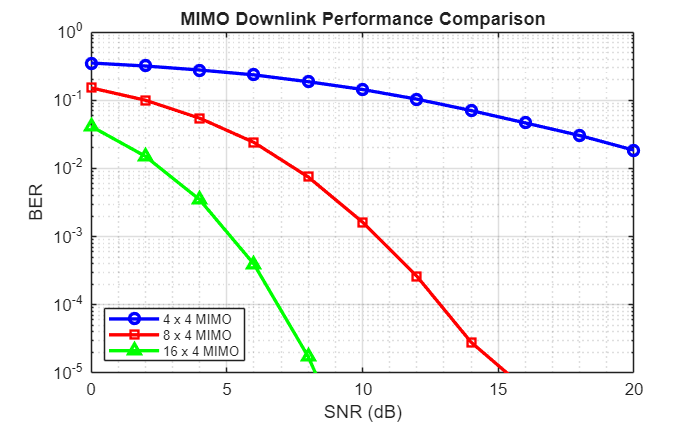


% --- GÖRSELLEŞTİRME ---
figure;
semilogy(SNR_dB, BER_results(:,1), 'o-b', 'LineWidth', 2, 'MarkerSize', 6); hold on;
semilogy(SNR_dB, BER_results(:,2), 's-r', 'LineWidth', 2, 'MarkerSize', 6);
semilogy(SNR_dB, BER_results(:,3), '^-g', 'LineWidth', 2,'MarkerSize', 6);
grid on;
grid minor;
xlabel('SNR (dB)'); ylabel('BER');
% Grafik kısmındaki axis komutunu güncelle:
title('MIMO Downlink Performance Comparison');
legend(sprintf('%d x %d MIMO', M_verici_vektoru(1),M_alici), ...
       sprintf('%d x %d MIMO', M_verici_vektoru(2),M_alici), ...
       sprintf('%d x %d MIMO', M_verici_vektoru(3),M_alici), ...
       'Location', 'southwest', 'FontSize', 8);


ylim([(1e-5 - 1e-16) 1]);              % <-- BU SATIRI EKLE
xlim([min(SNR_dB) max(SNR_dB)]);